% %%%
% % fgm_bdata;
% shock_normal;
% AA = dot(fgm_bdata(1,1:3)/norm(fgm_bdata(1,1:3)),shock_normal)
% rad2deg(acos(AA))
% norm(fgm_bdata(1,1:3))
% fgm_bdata(1,1:3)/norm(fgm_bdata(1,1:3)).*shock_normal
%
% BB = sum(fgm_bdata(1,1:3).*shock_normal/norm(fgm_bdata(1,1:3)))
% rad2deg(acos(BB))
%
% CC = sum(fgm_bdata(1,1:3).*shock_normal/vecnorm(fgm_bdata(1,1:3),2),2)
%
% vecnorm(fgm_bdata(1,1:3))
%
%
% vecnorm(fgm_bdata(:,1:3),3,2)
%
% rad2deg(acos(sum(fgm_bdata(:,1:3).*shock_normal./vecnorm(fgm_bdata(:,1:3),2),2)))
%
% vecnorm(fgm_bdata(:,1:3),2,2)
% rad2deg(acos(sum(fgm_bdata(:,1:3).*shock_normal./vecnorm(fgm_bdata(:,1:3),2,2),2)))
% %%%


% %date_start = '2018-03-01 01:05:40.000';
% %date_end = '2018-03-01 01:06:22.000';
% date_start = '2018-01-09 08:34:28.000';
% date_end = '2018-01-09 08:34:59.000';
% % formatIn='yyyy-mm-dd HH:MM:SS.FFF';
% %
% % tstart = datenum(date_start,formatIn);
% % tend = datenum(date_end,formatIn);
% probe_num = '1';
%
% %load mec data
% [mms1_mec_timedata,mms1_mec_r_gsedata] = load_mec(date_start,'1',data_type);
% [mms2_mec_timedata,mms2_mec_r_gsedata] = load_mec(date_start,'2',data_type);
% [mms3_mec_timedata,mms3_mec_r_gsedata] = load_mec(date_start,'3',data_type);
% [mms4_mec_timedata,mms4_mec_r_gsedata] = load_mec(date_start,'4',data_type);
%
% %load fgm data
% [mms1_fgm_timedata, mms1_fgm_bdata,~,~]= load_fgm(date_start,'1',data_type);
% [mms2_fgm_timedata, mms2_fgm_bdata,~,~]= load_fgm(date_start,'2',data_type);
% [mms3_fgm_timedata, mms3_fgm_bdata,~,~]= load_fgm(date_start,'3',data_type);
% [mms4_fgm_timedata, mms4_fgm_bdata,~,~]= load_fgm(date_start,'4',data_type);
%
% %interpolate with mms1_btime
% [~,mms1_mec_r_gsedata] = interpxyz(mms1_mec_timedata,mms1_mec_r_gsedata,mms1_fgm_timedata);
%
% [~,mms2_fgm_bdata] = interpxyz(mms2_fgm_timedata,mms2_fgm_bdata,mms1_fgm_timedata);
% [~,mms2_mec_r_gsedata] = interpxyz(mms2_mec_timedata,mms2_mec_r_gsedata,mms1_fgm_timedata);
%
% [~,mms3_fgm_bdata] = interpxyz(mms3_fgm_timedata,mms3_fgm_bdata,mms1_fgm_timedata);
% [~,mms3_mec_r_gsedata] = interpxyz(mms3_mec_timedata,mms3_mec_r_gsedata,mms1_fgm_timedata);
%
% [~,mms4_fgm_bdata] = interpxyz(mms4_fgm_timedata,mms4_fgm_bdata,mms1_fgm_timedata);
% [~,mms4_mec_r_gsedata] = interpxyz(mms4_mec_timedata,mms4_mec_r_gsedata,mms1_fgm_timedata);
%
%
% %crop data to specific time period
% [mms1_mec_timedata,mms1_mec_r_gsedata,~,~] = crop(mms1_mec_timedata,mms1_mec_r_gsedata,date_start,date_end);
% [mms2_mec_timedata,mms2_mec_r_gsedata,~,~] = crop(mms2_mec_timedata,mms2_mec_r_gsedata,date_start,date_end);
% [mms3_mec_timedata,mms3_mec_r_gsedata,~,~] = crop(mms3_mec_timedata,mms3_mec_r_gsedata,date_start,date_end);
% [mms4_mec_timedata,mms4_mec_r_gsedata,~,~] = crop(mms4_mec_timedata,mms4_mec_r_gsedata,date_start,date_end);
%
% [mms1_fgm_timedata,mms1_fgm_bdata,~,~] = crop(mms1_fgm_timedata,mms1_fgm_bdata,date_start,date_end);
% [mms2_fgm_timedata,mms2_fgm_bdata,~,~] = crop(mms2_fgm_timedata,mms2_fgm_bdata,date_start,date_end);
% [mms3_fgm_timedata,mms3_fgm_bdata,~,~] = crop(mms3_fgm_timedata,mms3_fgm_bdata,date_start,date_end);
% [mms4_fgm_timedata,mms4_fgm_bdata,~,~] = crop(mms4_fgm_timedata,mms4_fgm_bdata,date_start,date_end);
%
%
%
% %data_points total in time range
% all_data = length(mms1_fgm_timedata);
% half_data = min([floor(all_data/2),40]);
% quarter_data = floor(half_data/2);
%
% %create correlate vectors, xyz
% cc12 = zeros(half_data,3);
% cc13 = zeros(half_data,3);
% cc14 = zeros(half_data,3);
%
%
% %loop over i=0 to length/2 for bxyz for mms234
% for i=1:half_data %loop for each subsequent data point.
%     %timing window is 1/4 - 3/4 of time range of mms1_btime
%     for j=1:3 %loop for each xyz
%         temp_matrix = corrcoef(mms1_fgm_bdata(quarter_data:all_data-quarter_data,j),...
%             mms2_fgm_bdata(i:all_data-half_data+i,j));
%         cc12(i,j) =  temp_matrix(1,2);
%
%
%         temp_matrix = corrcoef(mms1_fgm_bdata(quarter_data:all_data-quarter_data,j),...
%             mms3_fgm_bdata(i:all_data-half_data+i,j));
%         cc13(i,j) = temp_matrix(1,2);
%
%
%         temp_matrix = corrcoef(mms1_fgm_bdata(quarter_data:all_data-quarter_data,j),...
%             mms4_fgm_bdata(i:all_data-half_data+i,j));
%         cc14(i,j) = temp_matrix(1,2);
%
%     end
%     %
%     %         cc12(i,2) = corrcoef(mms1_fgm_bdata(quarter_data:all_data-quarter_data,2),...
%     %             mms2_fgm_bdata(i:all_data-half_data+i,2));
%     %         cc12(i,3) = corrcoef(mms1_fgm_bdata(quarter_data:all_data-quarter_data,3),...
%     %             mms2_fgm_bdata(i:all_data-half_data+i,3));
%     %
%     %
%     %         cc13(i,2) = corrcoef(mms1_fgm_bdata(quarter_data:all_data-quarter_data,2),...
%     %             mms3_fgm_bdata(i:all_data-half_data+i,2));
%     %         cc13(i,3) = corrcoef(mms1_fgm_bdata(quarter_data:all_data-quarter_data,3),...
%     %             mms3_fgm_bdata(i:all_data-half_data+i,3));
%     %
%     %         cc14(i,2) = corrcoef(mms1_fgm_bdata(quarter_data:all_data-quarter_data,2),...
%     %             mms4_fgm_bdata(i:all_data-half_data+i,2));
%     %         cc14(i,3) = corrcoef(mms1_fgm_bdata(quarter_data:all_data-quarter_data,3),...
%     %             mms4_fgm_bdata(i:all_data-half_data+i,3));
% end
%
% %find the best match for correlation
%
% for i=1:3
%     [cc12max(i),cc12max_index(i)] = max(cc12(:,i));
%     [cc13max(i),cc13max_index(i)] = max(cc13(:,i));
%     [cc14max(i),cc14max_index(i)] = max(cc14(:,i));
% end
%
%
% %subscript is the strting point for btime and analysis
%
%
% %save its subscript, this subscript is the starting point of its btime
% %
% % now we have mms1_Btime cropped from 1/4 to 3/4
% mms1_fgm_bdata = mms1_fgm_bdata(quarter_data:all_data-quarter_data,:);
% mms1_fgm_bdata = mms1_fgm_bdata(quarter_data:all_data-quarter_data,:);
% %and mms2_btime,mms3,mms4 cropped from it's max correlate value to i+length/2
% %also crop its corresponding bdata and mec rdata
% %we only need the first time data point for analysis.
% %create t_alphabeta 6x1
% %create r_alphak -r_Betakv 6x3
% %create volumetric matrix, 3x3
% %1x6 6x3 3x3 = 1x3
% %1/(norm of (1x3)) = speed
%
%
%
%
% syms t12 t13 t14 t23 t24 t34
% T = [t12 t13 t14 t23 t24 t34]
%
% syms r12x r13x r14x r23x r24x r34x
% syms r12y r13y r14y r23y r24y r34y
% syms r12z r13z r14z r23z r24z r34z
% R = [r12x,r12y,r12z;r13x,r13y,r13z;r14x,r14y,r14z;r23x,r23y,r23z;r24x,r24y,r24z;r34x,r34y,r34z]
% T*R

% %Shock Angles
% B_pre = [-0.824,-2.24,.708]
% B_post = [1.95,1.17,1.38]
% N_bs=[0.974,-0.219,-0.054]
% Theta_Bpren = acosd(dot(B_pre,N_bs)/norm(B_pre))
% Theta_Bpostn=acosd(dot(B_post,N_bs)/norm(B_post))
% Theta_BpreBpost = acosd(dot(B_pre,B_post)/(norm(B_pre)*norm(B_post)))
%
% %Current Sheet Speeds, Use V_sw before Event
% V_pre = [-481,12,-12]
% V_post = [-495,3,-18]
% N_cs = [.680,-0.437,-0.590]
% V_ncspre = dot(V_pre,N_cs)
% V_ncspost = dot(V_post,N_cs)
% V_ncs=V_ncspre;
%
% %Electric field Direction to CS
% Epre = [19,-350,-1100]
% Epost = [-30,-650,600]
% dot(Epre,N_cs)
% dot(Epost,N_cs)
%
% %Angle between CS and BS
% Theta_csbs = acosd(dot(N_cs,N_bs))
% Theta_csswpre=acosd(dot(V_pre,N_cs)/norm(V_pre))
% Theta_bsswpre=acosd(dot(V_pre,N_bs)/norm(V_pre))
% Theta_csswpost=acosd(dot(V_post,N_cs)/norm(V_post))
% Theta_bsswpost=acosd(dot(V_post,N_bs)/norm(V_post))
%
%
% %Transversal Speed
% V_tr = V_ncs/(sind(Theta_csbs)^2)*(N_cs-N_bs*cosd(Theta_csbs))
% mag_V_tr = norm(V_tr)
%
% %Pre Vg
% V_g = 2 * dot(V_pre,N_bs) * sind(Theta_Bpren)
% V_tr_over_V_g = abs(mag_V_tr/V_g)
% V_tr_over_V_g_2 = (cosd(Theta_csswpre))/(2*cosd(Theta_bsswpre)*sind(Theta_Bpren)*sind(Theta_csbs))
%
%
% %Post Vg
% V_g = 2*dot(V_post,N_bs) * sind(Theta_Bpostn)
% V_tr_over_V_g = abs(mag_V_tr/V_g)
% V_tr_over_V_g_2 = (cosd(Theta_csswpost))/(2*cosd(Theta_bsswpost)*sind(Theta_Bpostn)*sind(Theta_csbs))
%
%
% %size
% Size = mag_V_tr*28/6371.2
% v1 = 234*[-0.340,0.633,0.696]
% v2 = -166*[0.861,+0.0007,-0.508]
% Delta_Vv = v2-v1
% Delta_V =(-234*[-0.340,0.633,0.696]-166*[0.861,+0.0007,-0.508])
% HFA_exp_V = abs(dot(Delta_V,N_cs))
%
% Event_age = Size/HFA_exp_V*6371.2
% Distance_traveled = Event_age*mag_V_tr/6371.2
%

% %Shock Angles
% B_pre = [1.351,-1.175,1.914];
% B_post = [3.27,-2.839,1.477];
% N_bs=[-0.1990,0.9750,-0.0990];
% Theta_Bpren = acosd(dot(B_pre,N_bs)/norm(B_pre))
% Theta_Bpostn=cosd(dot(B_post,N_bs)/norm(B_post))
% Theta_BpreBpost = acosd(dot(B_pre,B_post)/(norm(B_pre)*norm(B_post)))
%
% %Current Sheet Speeds, Use V_sw before Event
% V_pre = [-303.5,63.19,23.24];
% V_post = [-320,14.11,47.14];
% N_cs = [-0.4290,-0.7559,-.4945];
% % N_cs = [0.8042,-0.4479,-.3907];
% V_ncspre = dot(V_pre,N_cs);
% V_ncspost = dot(V_post,N_cs);
% V_ncs=V_ncspre
%
% %Electric field Direction to CS
% % Epre = [19,-350,-1100]
% % Epost = [-30,-650,600]
% % dot(Epre,N_cs)
% % dot(Epost,N_cs)
%
% %Angle between CS and BS
% Theta_csbs = acosd(dot(N_cs,N_bs))
% %Transversal Speed
% V_tr = V_ncs/((sind(Theta_csbs))^2)*(N_cs-N_bs*cosd(Theta_csbs))
% mag_V_tr = norm(V_tr)
%
% %angle with solar wind velocity
% Theta_csswpre=acosd(dot(V_pre,N_cs)/norm(V_pre))
% Theta_bsswpre=acosd(dot(V_pre,N_bs)/norm(V_pre))
% Theta_csswpost=acosd(dot(V_post,N_cs)/norm(V_post))
% Theta_bsswpost=acosd(dot(V_post,N_bs)/norm(V_post))
%
% %Pre Vg
% V_g = 2 * abs(dot(V_pre,N_bs) * sind(Theta_Bpren))
% V_tr_over_V_g = abs(mag_V_tr/V_g)
%
% %V_tr_over_V_g_2 = (cosd(Theta_csswpre))/(2*cosd(Theta_bsswpre)*sind(Theta_Bpren)*sind(Theta_csbs))
%
% %Post Vg
% V_g = 2*abs(dot(V_post,N_bs) * sind(Theta_Bpostn))
% V_tr_over_V_g = abs(mag_V_tr/V_g)
%
% %V_tr_over_V_g_2 = (cosd(Theta_csswpost))/(2*cosd(Theta_bsswpost)*sind(Theta_Bpostn)*sind(Theta_csbs))
%
%
% %size
% Size = mag_V_tr*22/6371.2
%
% Delta_V =(392*[-0.8962,0.2622,0.3579]-325*[-0.9935,-0.1139,-0.0010]);
% %HFA_exp_V = abs(dot(Delta_V,N_cs))
% Delta_V=(392-325);
% HFA_exp_V=norm(Delta_V.*N_cs)
%
%
% Event_age = Size/HFA_exp_V*6371.2
% Distance_traveled = Event_age*mag_V_tr/6371.2

% %Calculate bow shock normal
% r_gse = mec_r_gsedata(1,:)/6371.2;
% v_sw = norm(fpi_i_vdata(1,:))
% calculate_dynamic_pressure(fpi_i_ndata(1),fpi_i_vdata(1,:),'i')
% bowshockmodel(r_gse,v_sw,dynamic_pressure)

%TDnormal with mean of 2 minutes.
figure
num_plots = 3;
event_start = '2017-12-29 18:10:55.000';
event_end = '2017-12-29 18:12:25.000';

leading_start  = '2017-12-29 18:11:16.750';
leading_end    = '2017-12-29 18:11:18.500';

trailing_start = '2017-12-29 18:11:52.750';
trailing_end   = '2017-12-29 18:11:54.750';

[mms1_fgm_timedata_srvy, mms1_fgm_bdata_srvy] = load_fgm(event_start,event_end,1,'srvy');

%get indices of event
[~,~,start_index,end_index] = crop(mms1_fgm_timedata_srvy,mms1_fgm_bdata_srvy,event_start,event_end);

%leading edge mean, upstream of 2 minutes
%calculate mean
%calculate variance; (each data points - mean)^2.
%standard deviation = sqrt(variance);
%if next point is larger than 1 standard deviation, stop.
interval = 1; %1second interval for means.
initial_gap = 2; %number of seconds to start analysis from the summary plot edges, which is start_index and end_index, <5s
threshold_std = 3;
leftmost_index = 0;
start_index_event = start_index+16*initial_gap; %index where event starts.

leading_mean = mean(mms1_fgm_bdata_srvy(start_index:start_index_event,4));
leading_std = std(mms1_fgm_bdata_srvy(start_index:start_index_event,4));


for i = 1:120*interval %240 half-seconds
    
    leading_left_index = start_index-16*i*interval;
    leading_right_index = start_index-16*(i-1)*interval;
    
    leading_next_mean = mean(mms1_fgm_bdata_srvy(leading_left_index:leading_right_index,4));
    
    if leading_next_mean-leading_mean > threshold_std*leading_std
        
        leading_mean = mean(mms1_fgm_bdata_srvy(leading_right_index:start_index_event,4));
        
        %leftmost edge where B is within threshold_std sigma of change to the event
        %edge.
        leftmost_index = leading_right_index;
        
        break;
    elseif leading_next_mean-leading_mean <= threshold_std*leading_std
        leading_mean = mean(mms1_fgm_bdata_srvy(leading_left_index:start_index_event,4));
        leading_std = std(mms1_fgm_bdata_srvy(leading_left_index:start_index_event,4));
    end
    
    if i==120*interval %if i=120seconds
        leading_mean = mean(mms1_fgm_bdata_srvy(leading_right_index:start_index_event,4));
        leftmost_index = leading_right_index;
        
    end
end

leftmost_index

leftmost_index = 2257

leading_mean

leading_mean = 3.7314







%trailing edge mean, upstream of up to 2 minutes.



rightmost_index = 0;
end_index_event = end_index-16*initial_gap; %index where event starts.

trailing_mean = mean(mms1_fgm_bdata_srvy(end_index_event:end_index,4))

trailing_mean = 3.6503

trailing_std = std(mms1_fgm_bdata_srvy(end_index_event:end_index,4))

trailing_std = 0.0946



for i = 1:120*interval %240 half-seconds
    i
    trailing_left_index = end_index+16*(i-1)*interval
    trailing_right_index = end_index+16*i*interval
    
    trailing_next_mean = mean(mms1_fgm_bdata_srvy(trailing_left_index:trailing_right_index,4))
    
    if trailing_next_mean-trailing_mean > threshold_std*trailing_std
        
        trailing_mean = mean(mms1_fgm_bdata_srvy(end_index_event:trailing_left_index,4))
        
        %rightmost edge where B is within threshold_std sigma of change to the event
        %edge.
        rightmost_index = trailing_left_index
        
        break;
    elseif trailing_next_mean-trailing_mean <= threshold_std*trailing_std
        trailing_mean = mean(mms1_fgm_bdata_srvy(start_index_event:trailing_right_index,4))
        leading_std = std(mms1_fgm_bdata_srvy(start_index_event:trailing_right_index,4))
    end
    
    if i ==120*interval %if i=2minutes.
        trailing_mean = mean(mms1_fgm_bdata_srvy(end_index_event:trailing_left_index,4))
        rightmost_index = trailing_left_index
    end
end

i = 1

trailing_left_index = 3841

trailing_right_index = 3857

trailing_next_mean = 3.8815

trailing_mean = 5.1650

leading_std = 3.4122

i = 2

trailing_left_index = 3857

trailing_right_index = 3873

trailing_next_mean = 3.9603

trailing_mean = 5.1513

leading_std = 3.3952

i = 3

trailing_left_index = 3873

trailing_right_index = 3889

trailing_next_mean = 3.8710

trailing_mean = 5.1368

leading_std = 3.3789

i = 4

trailing_left_index = 3889

trailing_right_index = 3905

trailing_next_mean = 3.7990

trailing_mean = 5.1219

leading_std = 3.3630

i = 5

trailing_left_index = 3905

trailing_right_index = 3921

trailing_next_mean = 3.7860

trailing_mean = 5.1072

leading_std = 3.3473

i = 6

trailing_left_index = 3921

trailing_right_index = 3937

trailing_next_mean = 3.8549

trailing_mean = 5.0936

leading_std = 3.3316

i = 7

trailing_left_index = 3937

trailing_right_index = 3953

trailing_next_mean = 3.8198

trailing_mean = 5.0799

leading_std = 3.3163

i = 8

trailing_left_index = 3953

trailing_right_index = 3969

trailing_next_mean = 3.7538

trailing_mean = 5.0658

leading_std = 3.3014

i = 9

trailing_left_index = 3969

trailing_right_index = 3985

trailing_next_mean = 3.7157

trailing_mean = 5.0516

leading_std = 3.2869

i = 10

trailing_left_index = 3985

trailing_right_index = 4001

trailing_next_mean = 3.7249

trailing_mean = 5.0378

leading_std = 3.2725

i = 11

trailing_left_index = 4001

trailing_right_index = 4017

trailing_next_mean = 3.7615

trailing_mean = 5.0246

leading_std = 3.2582

i = 12

trailing_left_index = 4017

trailing_right_index = 4033

trailing_next_mean = 3.7649

trailing_mean = 5.0117

leading_std = 3.2440

i = 13

trailing_left_index = 4033

trailing_right_index = 4049

trailing_next_mean = 3.7646

trailing_mean = 4.9991

leading_std = 3.2300

i = 14

trailing_left_index = 4049

trailing_right_index = 4065

trailing_next_mean = 3.7827

trailing_mean = 4.9869

leading_std = 3.2161

i = 15

trailing_left_index = 4065

trailing_right_index = 4081

trailing_next_mean = 3.7698

trailing_mean = 4.9749

leading_std = 3.2024

i = 16

trailing_left_index = 4081

trailing_right_index = 4097

trailing_next_mean = 3.8197

trailing_mean = 4.9636

leading_std = 3.1887

i = 17

trailing_left_index = 4097

trailing_right_index = 4113

trailing_next_mean = 3.8096

trailing_mean = 4.9524

leading_std = 3.1752

i = 18

trailing_left_index = 4113

trailing_right_index = 4129

trailing_next_mean = 3.7389

trailing_mean = 4.9407

leading_std = 3.1621

i = 19

trailing_left_index = 4129

trailing_right_index = 4145

trailing_next_mean = 3.7357

trailing_mean = 4.9293

leading_std = 3.1492

i = 20

trailing_left_index = 4145

trailing_right_index = 4161

trailing_next_mean = 3.7416

trailing_mean = 4.9181

leading_std = 3.1364

i = 21

trailing_left_index = 4161

trailing_right_index = 4177

trailing_next_mean = 3.7198

trailing_mean = 4.9069

leading_std = 3.1238

i = 22

trailing_left_index = 4177

trailing_right_index = 4193

trailing_next_mean = 3.6793

trailing_mean = 4.8955

leading_std = 3.1116

i = 23

trailing_left_index = 4193

trailing_right_index = 4209

trailing_next_mean = 3.6361

trailing_mean = 4.8839

leading_std = 3.0996

i = 24

trailing_left_index = 4209

trailing_right_index = 4225

trailing_next_mean = 3.6769

trailing_mean = 4.8730

leading_std = 3.0876

i = 25

trailing_left_index = 4225

trailing_right_index = 4241

trailing_next_mean = 3.7728

trailing_mean = 4.8631

leading_std = 3.0754

i = 26

trailing_left_index = 4241

trailing_right_index = 4257

trailing_next_mean = 3.8082

trailing_mean = 4.8537

leading_std = 3.0632

i = 27

trailing_left_index = 4257

trailing_right_index = 4273

trailing_next_mean = 3.8285

trailing_mean = 4.8446

leading_std = 3.0512

i = 28

trailing_left_index = 4273

trailing_right_index = 4289

trailing_next_mean = 3.8397

trailing_mean = 4.8358

leading_std = 3.0392

i = 29

trailing_left_index = 4289

trailing_right_index = 4305

trailing_next_mean = 3.7491

trailing_mean = 4.8263

leading_std = 3.0277

i = 30

trailing_left_index = 4305

trailing_right_index = 4321

trailing_next_mean = 3.6395

trailing_mean = 4.8161

leading_std = 3.0166

i = 31

trailing_left_index = 4321

trailing_right_index = 4337

trailing_next_mean = 3.6389

trailing_mean = 4.8060

leading_std = 3.0056

i = 32

trailing_left_index = 4337

trailing_right_index = 4353

trailing_next_mean = 3.6159

trailing_mean = 4.7959

leading_std = 2.9949

i = 33

trailing_left_index = 4353

trailing_right_index = 4369

trailing_next_mean = 3.5928

trailing_mean = 4.7858

leading_std = 2.9843

i = 34

trailing_left_index = 4369

trailing_right_index = 4385

trailing_next_mean = 3.5933

trailing_mean = 4.7759

leading_std = 2.9738

i = 35

trailing_left_index = 4385

trailing_right_index = 4401

trailing_next_mean = 3.5967

trailing_mean = 4.7662

leading_std = 2.9634

i = 36

trailing_left_index = 4401

trailing_right_index = 4417

trailing_next_mean = 3.5913

trailing_mean = 4.7565

leading_std = 2.9531

i = 37

trailing_left_index = 4417

trailing_right_index = 4433

trailing_next_mean = 3.6125

trailing_mean = 4.7472

leading_std = 2.9429

i = 38

trailing_left_index = 4433

trailing_right_index = 4449

trailing_next_mean = 3.6792

trailing_mean = 4.7387

leading_std = 2.9325

i = 39

trailing_left_index = 4449

trailing_right_index = 4465

trailing_next_mean = 3.6689

trailing_mean = 4.7301

leading_std = 2.9223

i = 40

trailing_left_index = 4465

trailing_right_index = 4481

trailing_next_mean = 3.6467

trailing_mean = 4.7215

leading_std = 2.9123

i = 41

trailing_left_index = 4481

trailing_right_index = 4497

trailing_next_mean = 3.6639

trailing_mean = 4.7132

leading_std = 2.9023

i = 42

trailing_left_index = 4497

trailing_right_index = 4513

trailing_next_mean = 3.6222

trailing_mean = 4.7047

leading_std = 2.8926

i = 43

trailing_left_index = 4513

trailing_right_index = 4529

trailing_next_mean = 3.5822

trailing_mean = 4.6959

leading_std = 2.8830

i = 44

trailing_left_index = 4529

trailing_right_index = 4545

trailing_next_mean = 3.6151

trailing_mean = 4.6876

leading_std = 2.8735

i = 45

trailing_left_index = 4545

trailing_right_index = 4561

trailing_next_mean = 3.6226

trailing_mean = 4.6795

leading_std = 2.8640

i = 46

trailing_left_index = 4561

trailing_right_index = 4577

trailing_next_mean = 3.6053

trailing_mean = 4.6714

leading_std = 2.8546

i = 47

trailing_left_index = 4577

trailing_right_index = 4593

trailing_next_mean = 3.5750

trailing_mean = 4.6631

leading_std = 2.8455

i = 48

trailing_left_index = 4593

trailing_right_index = 4609

trailing_next_mean = 3.6995

trailing_mean = 4.6560

leading_std = 2.8360

i = 49

trailing_left_index = 4609

trailing_right_index = 4625

trailing_next_mean = 3.7332

trailing_mean = 4.6492

leading_std = 2.8266

i = 50

trailing_left_index = 4625

trailing_right_index = 4641

trailing_next_mean = 3.7048

trailing_mean = 4.6422

leading_std = 2.8173

i = 51

trailing_left_index = 4641

trailing_right_index = 4657

trailing_next_mean = 3.7721

trailing_mean = 4.6359

leading_std = 2.8080

i = 52

trailing_left_index = 4657

trailing_right_index = 4673

trailing_next_mean = 3.8079

trailing_mean = 4.6299

leading_std = 2.7987

i = 53

trailing_left_index = 4673

trailing_right_index = 4689

trailing_next_mean = 3.7215

trailing_mean = 4.6233

leading_std = 2.7897

i = 54

trailing_left_index = 4689

trailing_right_index = 4705

trailing_next_mean = 3.6936

trailing_mean = 4.6167

leading_std = 2.7808

i = 55

trailing_left_index = 4705

trailing_right_index = 4721

trailing_next_mean = 3.7436

trailing_mean = 4.6105

leading_std = 2.7719

i = 56

trailing_left_index = 4721

trailing_right_index = 4737

trailing_next_mean = 3.7853

trailing_mean = 4.6047

leading_std = 2.7630

i = 57

trailing_left_index = 4737

trailing_right_index = 4753

trailing_next_mean = 3.8622

trailing_mean = 4.5996

leading_std = 2.7540

i = 58

trailing_left_index = 4753

trailing_right_index = 4769

trailing_next_mean = 3.8068

trailing_mean = 4.5940

leading_std = 2.7452

i = 59

trailing_left_index = 4769

trailing_right_index = 4785

trailing_next_mean = 3.8095

trailing_mean = 4.5886

leading_std = 2.7365

i = 60

trailing_left_index = 4785

trailing_right_index = 4801

trailing_next_mean = 3.7956

trailing_mean = 4.5832

leading_std = 2.7279

i = 61

trailing_left_index = 4801

trailing_right_index = 4817

trailing_next_mean = 3.6544

trailing_mean = 4.5768

leading_std = 2.7197

i = 62

trailing_left_index = 4817

trailing_right_index = 4833

trailing_next_mean = 3.5771

trailing_mean = 4.5701

leading_std = 2.7117

i = 63

trailing_left_index = 4833

trailing_right_index = 4849

trailing_next_mean = 3.5372

trailing_mean = 4.5631

leading_std = 2.7039

i = 64

trailing_left_index = 4849

trailing_right_index = 4865

trailing_next_mean = 3.5507

trailing_mean = 4.5564

leading_std = 2.6962

i = 65

trailing_left_index = 4865

trailing_right_index = 4881

trailing_next_mean = 3.6174

trailing_mean = 4.5502

leading_std = 2.6883

i = 66

trailing_left_index = 4881

trailing_right_index = 4897

trailing_next_mean = 3.7738

trailing_mean = 4.5451

leading_std = 2.6802

i = 67

trailing_left_index = 4897

trailing_right_index = 4913

trailing_next_mean = 3.8554

trailing_mean = 4.5406

leading_std = 2.6720

i = 68

trailing_left_index = 4913

trailing_right_index = 4929

trailing_next_mean = 3.9348

trailing_mean = 4.5367

leading_std = 2.6637

i = 69

trailing_left_index = 4929

trailing_right_index = 4945

trailing_next_mean = 4.0365

trailing_mean = 4.5335

leading_std = 2.6554

i = 70

trailing_left_index = 4945

trailing_right_index = 4961

trailing_next_mean = 4.0011

trailing_mean = 4.5301

leading_std = 2.6472

i = 71

trailing_left_index = 4961

trailing_right_index = 4977

trailing_next_mean = 3.9346

trailing_mean = 4.5263

leading_std = 2.6392

i = 72

trailing_left_index = 4977

trailing_right_index = 4993

trailing_next_mean = 3.9162

trailing_mean = 4.5224

leading_std = 2.6313

i = 73

trailing_left_index = 4993

trailing_right_index = 5009

trailing_next_mean = 3.8936

trailing_mean = 4.5184

leading_std = 2.6235

i = 74

trailing_left_index = 5009

trailing_right_index = 5025

trailing_next_mean = 3.8583

trailing_mean = 4.5143

leading_std = 2.6158

i = 75

trailing_left_index = 5025

trailing_right_index = 5041

trailing_next_mean = 3.8271

trailing_mean = 4.5101

leading_std = 2.6082

i = 76

trailing_left_index = 5041

trailing_right_index = 5057

trailing_next_mean = 3.8461

trailing_mean = 4.5060

leading_std = 2.6007

i = 77

trailing_left_index = 5057

trailing_right_index = 5073

trailing_next_mean = 3.8168

trailing_mean = 4.5017

leading_std = 2.5932

i = 78

trailing_left_index = 5073

trailing_right_index = 5089

trailing_next_mean = 3.7642

trailing_mean = 4.4972

leading_std = 2.5860

i = 79

trailing_left_index = 5089

trailing_right_index = 5105

trailing_next_mean = 3.6895

trailing_mean = 4.4923

leading_std = 2.5789

i = 80

trailing_left_index = 5105

trailing_right_index = 5121

trailing_next_mean = 3.5971

trailing_mean = 4.4869

leading_std = 2.5720

i = 81

trailing_left_index = 5121

trailing_right_index = 5137

trailing_next_mean = 3.5679

trailing_mean = 4.4814

leading_std = 2.5653

i = 82

trailing_left_index = 5137

trailing_right_index = 5153

trailing_next_mean = 3.5537

trailing_mean = 4.4759

leading_std = 2.5587

i = 83

trailing_left_index = 5153

trailing_right_index = 5169

trailing_next_mean = 3.5568

trailing_mean = 4.4705

leading_std = 2.5521

i = 84

trailing_left_index = 5169

trailing_right_index = 5185

trailing_next_mean = 3.6151

trailing_mean = 4.4655

leading_std = 2.5454

i = 85

trailing_left_index = 5185

trailing_right_index = 5201

trailing_next_mean = 3.6640

trailing_mean = 4.4608

leading_std = 2.5387

i = 86

trailing_left_index = 5201

trailing_right_index = 5217

trailing_next_mean = 3.6224

trailing_mean = 4.4559

leading_std = 2.5321

i = 87

trailing_left_index = 5217

trailing_right_index = 5233

trailing_next_mean = 3.6635

trailing_mean = 4.4513

leading_std = 2.5255

i = 88

trailing_left_index = 5233

trailing_right_index = 5249

trailing_next_mean = 3.7170

trailing_mean = 4.4471

leading_std = 2.5188

i = 89

trailing_left_index = 5249

trailing_right_index = 5265

trailing_next_mean = 3.7292

trailing_mean = 4.4430

leading_std = 2.5122

i = 90

trailing_left_index = 5265

trailing_right_index = 5281

trailing_next_mean = 3.7043

trailing_mean = 4.4388

leading_std = 2.5056

i = 91

trailing_left_index = 5281

trailing_right_index = 5297

trailing_next_mean = 3.6792

trailing_mean = 4.4345

leading_std = 2.4992

i = 92

trailing_left_index = 5297

trailing_right_index = 5313

trailing_next_mean = 3.6181

trailing_mean = 4.4299

leading_std = 2.4929

i = 93

trailing_left_index = 5313

trailing_right_index = 5329

trailing_next_mean = 3.6190

trailing_mean = 4.4254

leading_std = 2.4867

i = 94

trailing_left_index = 5329

trailing_right_index = 5345

trailing_next_mean = 3.6411

trailing_mean = 4.4210

leading_std = 2.4805

i = 95

trailing_left_index = 5345

trailing_right_index = 5361

trailing_next_mean = 3.6222

trailing_mean = 4.4166

leading_std = 2.4743

i = 96

trailing_left_index = 5361

trailing_right_index = 5377

trailing_next_mean = 3.6152

trailing_mean = 4.4122

leading_std = 2.4682

i = 97

trailing_left_index = 5377

trailing_right_index = 5393

trailing_next_mean = 3.6024

trailing_mean = 4.4078

leading_std = 2.4622

i = 98

trailing_left_index = 5393

trailing_right_index = 5409

trailing_next_mean = 3.6310

trailing_mean = 4.4036

leading_std = 2.4561

i = 99

trailing_left_index = 5409

trailing_right_index = 5425

trailing_next_mean = 3.6139

trailing_mean = 4.3993

leading_std = 2.4502

i = 100

trailing_left_index = 5425

trailing_right_index = 5441

trailing_next_mean = 3.7055

trailing_mean = 4.3956

leading_std = 2.4441

i = 101

trailing_left_index = 5441

trailing_right_index = 5457

trailing_next_mean = 3.7290

trailing_mean = 4.3920

leading_std = 2.4381

i = 102

trailing_left_index = 5457

trailing_right_index = 5473

trailing_next_mean = 3.6631

trailing_mean = 4.3881

leading_std = 2.4321

i = 103

trailing_left_index = 5473

trailing_right_index = 5489

trailing_next_mean = 3.6303

trailing_mean = 4.3841

leading_std = 2.4263

i = 104

trailing_left_index = 5489

trailing_right_index = 5505

trailing_next_mean = 3.6425

trailing_mean = 4.3802

leading_std = 2.4205

i = 105

trailing_left_index = 5505

trailing_right_index = 5521

trailing_next_mean = 3.6523

trailing_mean = 4.3764

leading_std = 2.4147

i = 106

trailing_left_index = 5521

trailing_right_index = 5537

trailing_next_mean = 3.5787

trailing_mean = 4.3723

leading_std = 2.4091

i = 107

trailing_left_index = 5537

trailing_right_index = 5553

trailing_next_mean = 3.6025

trailing_mean = 4.3683

leading_std = 2.4035

i = 108

trailing_left_index = 5553

trailing_right_index = 5569

trailing_next_mean = 3.6294

trailing_mean = 4.3645

leading_std = 2.3979

i = 109

trailing_left_index = 5569

trailing_right_index = 5585

trailing_next_mean = 3.6481

trailing_mean = 4.3608

leading_std = 2.3923

i = 110

trailing_left_index = 5585

trailing_right_index = 5601

trailing_next_mean = 3.6162

trailing_mean = 4.3570

leading_std = 2.3868

i = 111

trailing_left_index = 5601

trailing_right_index = 5617

trailing_next_mean = 3.6037

trailing_mean = 4.3532

leading_std = 2.3813

i = 112

trailing_left_index = 5617

trailing_right_index = 5633

trailing_next_mean = 3.6544

trailing_mean = 4.3497

leading_std = 2.3758

i = 113

trailing_left_index = 5633

trailing_right_index = 5649

trailing_next_mean = 3.7089

trailing_mean = 4.3465

leading_std = 2.3703

i = 114

trailing_left_index = 5649

trailing_right_index = 5665

trailing_next_mean = 3.7460

trailing_mean = 4.3435

leading_std = 2.3647

i = 115

trailing_left_index = 5665

trailing_right_index = 5681

trailing_next_mean = 3.6526

trailing_mean = 4.3400

leading_std = 2.3593

i = 116

trailing_left_index = 5681

trailing_right_index = 5697

trailing_next_mean = 3.6477

trailing_mean = 4.3366

leading_std = 2.3540

i = 117

trailing_left_index = 5697

trailing_right_index = 5713

trailing_next_mean = 3.6805

trailing_mean = 4.3333

leading_std = 2.3486

i = 118

trailing_left_index = 5713

trailing_right_index = 5729

trailing_next_mean = 3.7126

trailing_mean = 4.3303

leading_std = 2.3433

i = 119

trailing_left_index = 5729

trailing_right_index = 5745

trailing_next_mean = 3.5272

trailing_mean = 4.3263

leading_std = 2.3382

i = 120

trailing_left_index = 5745

trailing_right_index = 5761

trailing_next_mean = 3.5157

trailing_mean = 4.3224

leading_std = 2.3332

trailing_mean = 3.7072

rightmost_index = 5745


rightmost_index

rightmost_index = 5745

trailing_mean

trailing_mean = 3.7072

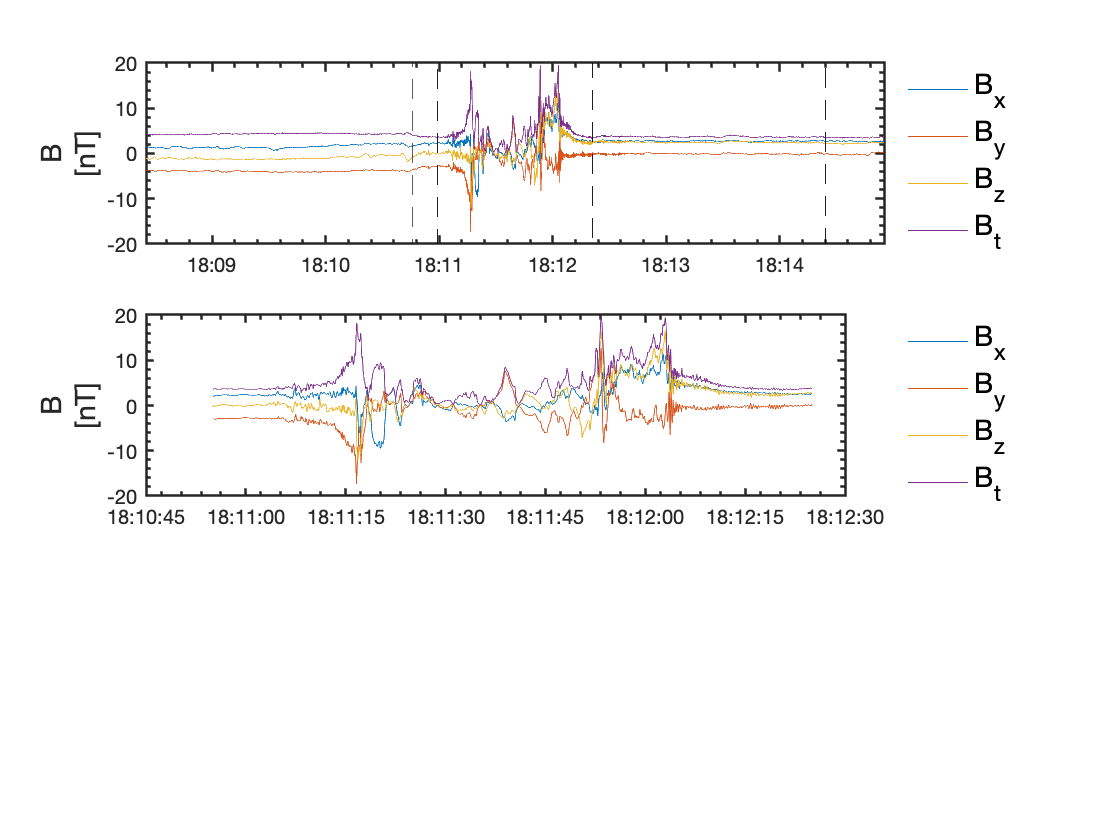




%plot entire range
subplot(num_plots,1,1)
plot(mms1_fgm_timedata_srvy,mms1_fgm_bdata_srvy);
hold on
line([(mms1_fgm_timedata_srvy(start_index_event)) (mms1_fgm_timedata_srvy(start_index_event))],...
    get(gca,'YLim'),'Color','k','LineWidth',0.5,'LineStyle','--')

line([(mms1_fgm_timedata_srvy(end_index_event)) (mms1_fgm_timedata_srvy(end_index_event))],...
    get(gca,'YLim'),'Color','k','LineWidth',0.5,'LineStyle','--')

line([(mms1_fgm_timedata_srvy(leftmost_index)) (mms1_fgm_timedata_srvy(leftmost_index))],...
    get(gca,'YLim'),'Color','k','LineWidth',0.5,'LineStyle','--')

line([(mms1_fgm_timedata_srvy(rightmost_index)) (mms1_fgm_timedata_srvy(rightmost_index))],...
    get(gca,'YLim'),'Color','k','LineWidth',0.5,'LineStyle','--')


hold off
legend({'B_x', 'B_y', 'B_z','B_t'},'FontSize',14)
legend('boxoff')
legend('Location','eastoutside')
colormap('winter');
datetick
xlim([mms1_fgm_timedata_srvy(1) mms1_fgm_timedata_srvy(end)])
ylabel({'B';'[nT]'},'FontSize', 14)
set(gca,'XMinorTick','on','YMinorTick','on','linewidth',1.25)

%plot event range.
plot_fgm_magnetic(event_start,event_end,mms1_fgm_timedata_srvy,mms1_fgm_bdata_srvy,num_plots,2)
datetick